# 学号：1851754  姓名：李玖思

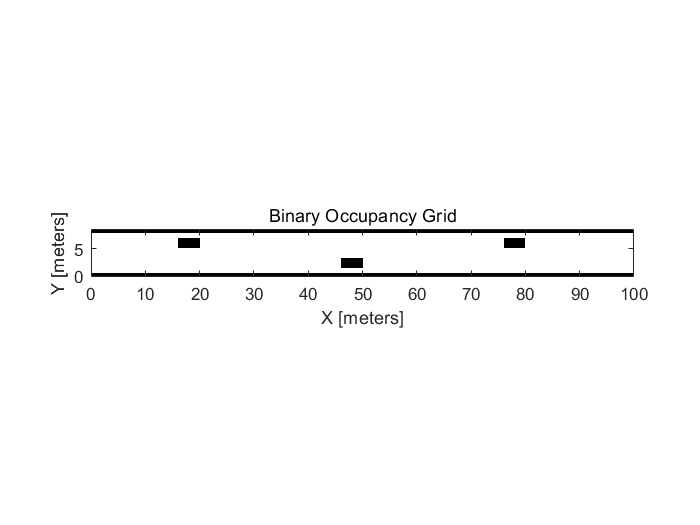

% 建立道路环境
map = binaryOccupancyMap(100, 8.5, 10);
occ = zeros(85, 1000);
occ([1:5,81:85],:) = 1;
occ(16:33,[161:200,761:800]) = 1;
occ(53:70,[461:500]) = 1;
setOccupancy(map, occ)
figure
show(map)

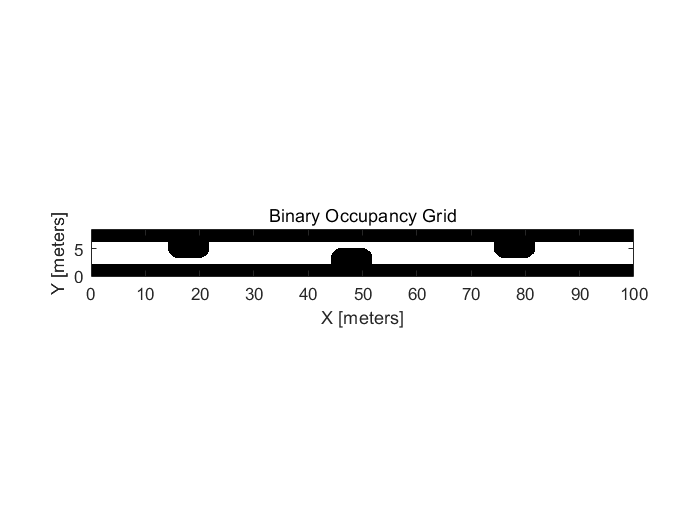

% 膨胀占据地图
inflate(map, 1.8)
show(map)

% A*算法规划路径

% 成本函数、启发函数为欧几里得距离
planner = plannerAStarGrid(map);
start = [0 6];
goal = [100 6];
[path1,Info1]=plan(planner,start,goal,"world");
Info1

Info1 = 包含以下字段的 struct :
            PathCost: 103.5451
    NumNodesExplored: 31680
         GCostMatrix: [85×1000 double]


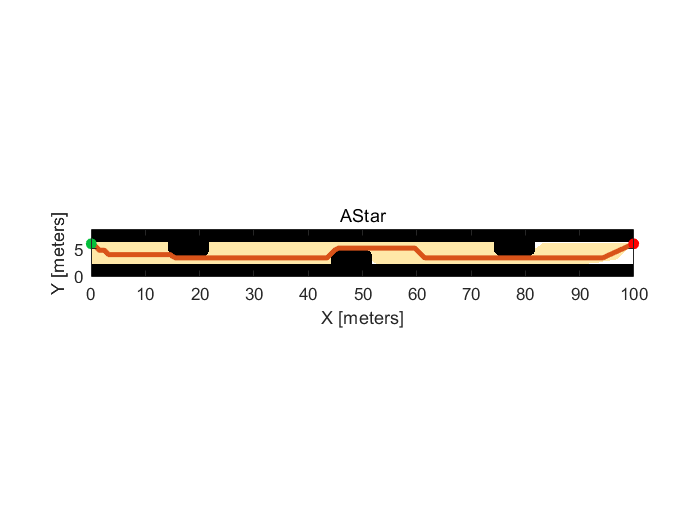

show(planner)

%成本函数为欧几里得距离，启发函数为0，退化为Dij
planner = plannerAStarGrid(map,'HCostFcn',@(pose1,pose2)0);
start = [0 6];
goal = [100 6];
[path2,Info2]=plan(planner,start,goal,"world");
Info2

Info2 = 包含以下字段的 struct :
            PathCost: 103.5451
    NumNodesExplored: 33018
         GCostMatrix: [85×1000 double]


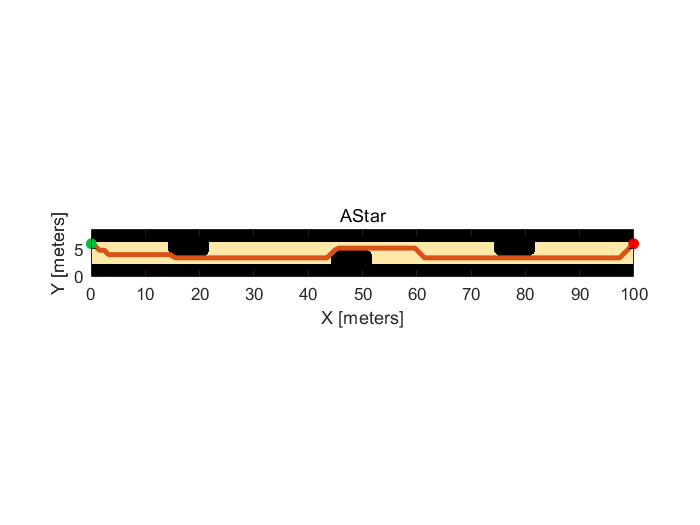

show(planner)

% 成本函数为欧几里得距离，启发函数为曼哈顿距离
planner = plannerAStarGrid(map,'HCost','Manhattan');
start = [0 6];
goal = [100 6];
[path3,Info3]=plan(planner,start,goal,"world");
Info3

Info3 = 包含以下字段的 struct :
            PathCost: 103.6279
    NumNodesExplored: 23351
         GCostMatrix: [85×1000 double]


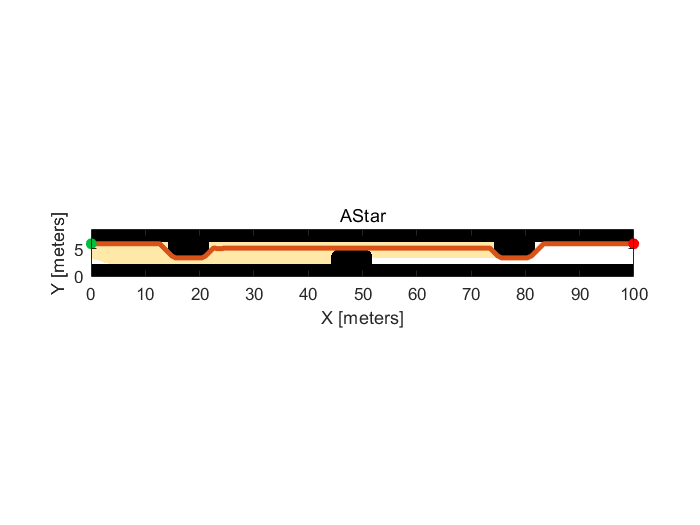

show(planner)

% 成本函数为欧几里得距离，启发函数为切比雪夫距离
planner = plannerAStarGrid(map,'HCost','Chebyshev');
start = [0 6];
goal = [100 6];
[path4,Info4]=plan(planner,start,goal,"world");
Info4

Info4 = 包含以下字段的 struct :
            PathCost: 103.5451
    NumNodesExplored: 32128
         GCostMatrix: [85×1000 double]


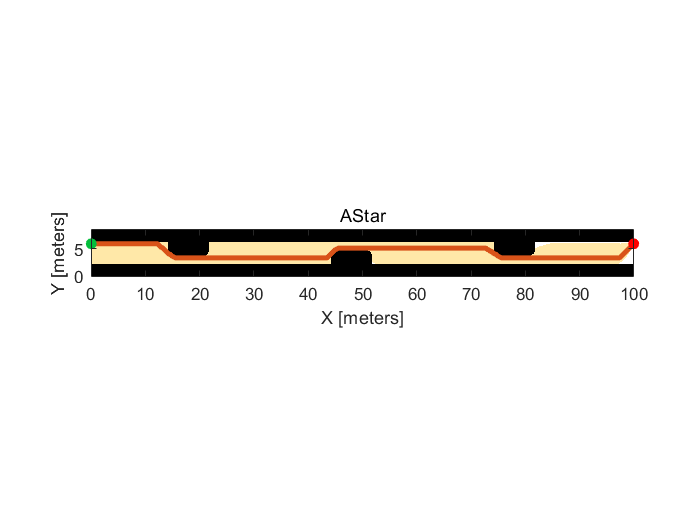

show(planner)

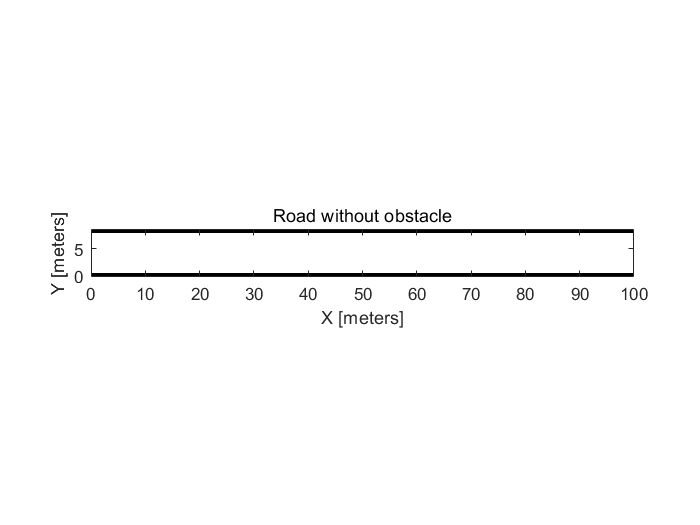

% 构建无障碍物的道路环境
estMap = occupancyMap(100, 8.5, 10);
occ = zeros(85, 1000);
occ([1:5,81:85],:) = 1;
setOccupancy(estMap, occ)
figure
show(estMap)
title('Road without obstacle')

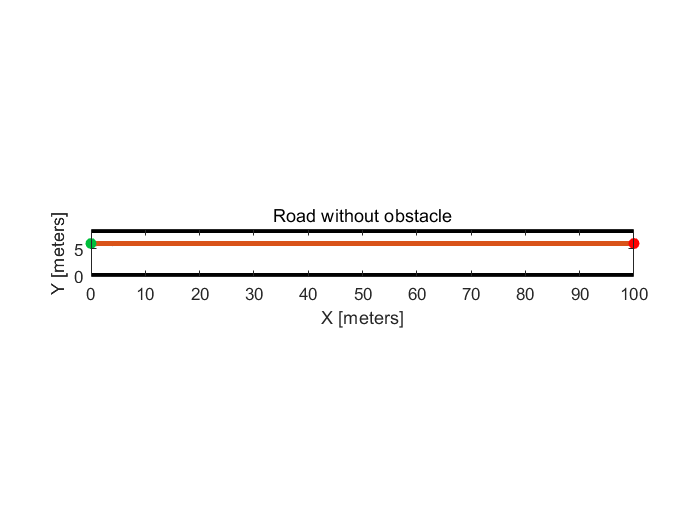

%生成无障碍物下的路径作为初始路径
inflateMap = occupancyMap(estMap);
vMap = validatorOccupancyMap; 
% ValidatorOccupencyMap对象根据占据栅格地图中的值验证运动。
vMap.Map = inflateMap;
vMap.ValidationDistance = .1;
% 检查栅格状态有效性的间隔为0.1（有效路径上可按0.1间隔插值）
planner = plannerHybridAStar(vMap, 'MinTurningRadius', 4);% 最小转弯半径为4
start = [0 6 0];
goal = [100 6 0];
route = plan(planner, start, goal);
route = route.States;
rsConn = reedsSheppConnection('MinTurningRadius', planner.MinTurningRadius);
startPoses = route(1:end-1,:);
endPoses = route(2:end,:);

rsPathSegs = connect(rsConn, startPoses, endPoses);
poses = [];
for i = 1:numel(rsPathSegs)
    lengths = 0:0.1:rsPathSegs{i}.Length;
    [pose, ~] = interpolate(rsPathSegs{i}, lengths);
    poses = [poses; pose];
end

figure
show(planner)
title('Road without obstacle')

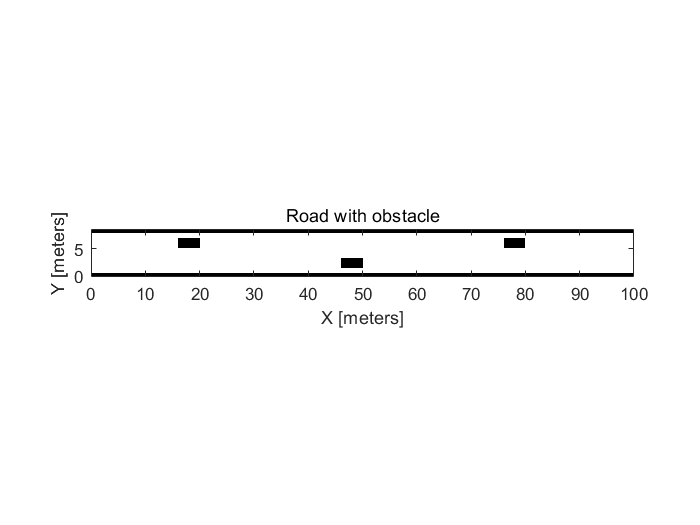

% 生成存在障碍物的道路环境
map = binaryOccupancyMap(100, 8.5, 10);
occ = zeros(85, 1000);
occ([1:5,81:85],:) = 1;
occ(16:33,[161:200,761:800]) = 1;
occ(53:70,[461:500]) = 1;
setOccupancy(map, occ)
figure
show(map)
title('Road with obstacle')

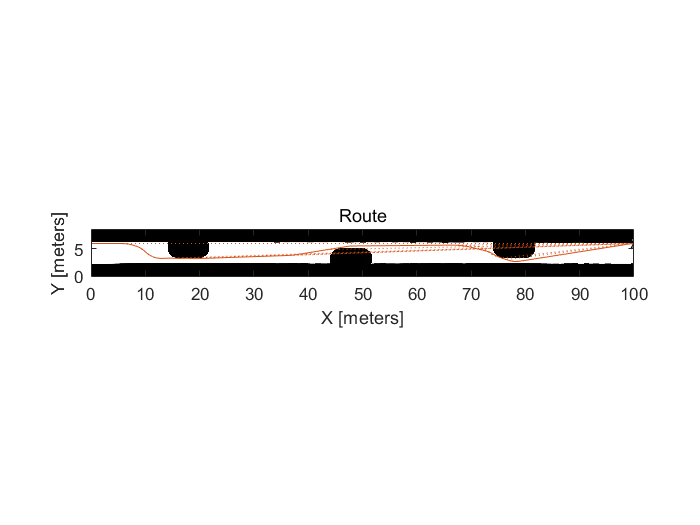

% rangeSensor距离传感器系统对象是一种距离方位传感器，能够根据给定的传感器姿势和占用地图输出距离和角度测量值。
rangefinder = rangeSensor('HorizontalAngle', pi/3); % 水平探测角度范围为 -60°~60°
numReadings = rangefinder.NumReadings; % 探测角度范围内的读数个数，与角度分辨率有关

% 根据测距仪读数动态更新路线
% 在汽车行驶过程中，从距离传感器获取障碍物信息，更新占据地图，如果原先规划的路径在更新地图中被占用，则重新规划，直到达到目标

helperViz = HelperUtils;
figure
show(inflateMap);
hold on
robotPatch = helperViz.plotRobot(gca, poses(1,:));
rangesLine = helperViz.plotScan(gca, poses(1,:), ...
    NaN(numReadings,1), ones(numReadings,1));
axesColors = get(gca, 'ColorOrder');
routeLine = helperViz.plotRoute(gca, route, axesColors(2,:));
traveledLine = plot(gca, NaN, NaN);
title('Route')
hold off
idx = 1;
tic;

% 检测路径上每一点之间有无障碍物
while idx <= size(poses,1)
    % 将距离传感器得到的障碍物信息加入estMap，即射线末端点被占有概率设为0.7
    [ranges, angles] = rangefinder(poses(idx,:), map);
    insertRay(estMap, poses(idx,:), ranges, angles, ...
        rangefinder.Range(end));
    
    % 用estMap更新inflateMap，即射线末端被占有的点按照1.8的半径膨胀
    setOccupancy(inflateMap, getOccupancy(estMap));
    inflate(inflateMap,1.8);

    % 可视化
    show(inflateMap, 'FastUpdate', true);
    helperViz.updateWorldMap(robotPatch, rangesLine, traveledLine, ...
        poses(idx,:), ranges, angles)
    drawnow
    
    % 在当前路线中检测到障碍物时重新生成路线
    isRouteOccupied = any(checkOccupancy(inflateMap, poses(:,1:2)));
    if isRouteOccupied && (toc > 0.1)
        % 重新规划路线
        route = plan(planner, poses(idx,:), goal);
        route = route.States;
        
        startPoses = route(1:end-1,:);
        endPoses = route(2:end,:);
        rsPathSegs = connect(rsConn, startPoses, endPoses);
        poses = [];
        for i = 1:numel(rsPathSegs)
            lengths = 0:0.1:rsPathSegs{i}.Length;
            [pose, ~] = interpolate(rsPathSegs{i}, lengths);
            poses = [poses; pose]; 
        end
        
        routeLine = helperViz.updateRoute(routeLine, route);
        idx = 1;
        tic;
    else
        idx = idx + 1;
    end
end